# **RB linkage **

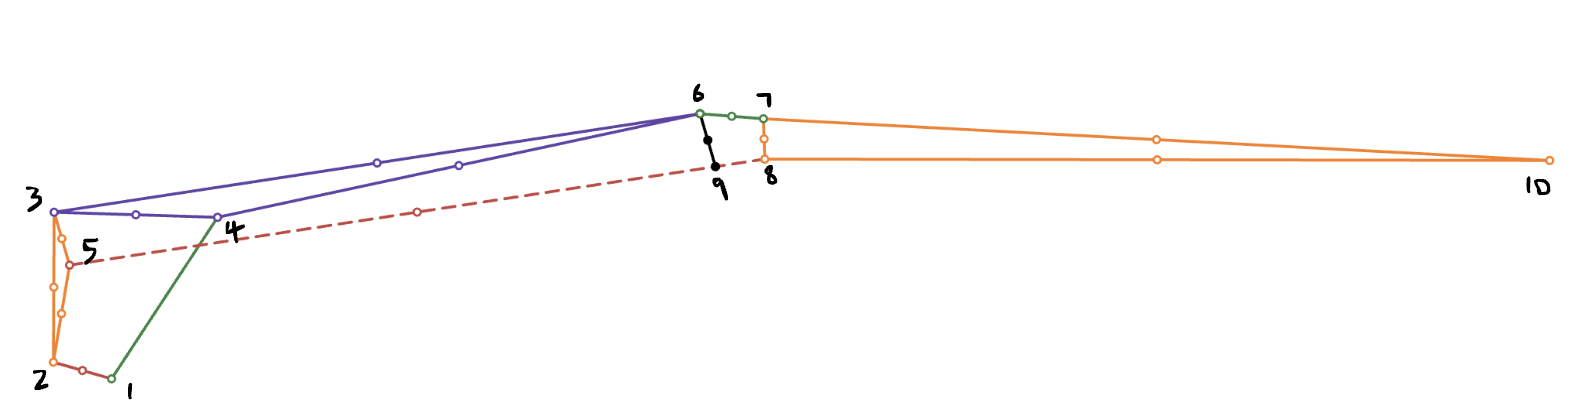

## **Parameters**

clear all; 
clc;


%% ───────── Major PARAMETERS ─────────
syms t 
syms t_d % drive angle (rad)
rho_air = 1.225; % kg/m^3
g = 9.81; % m/s^2

% Base length scale
L12 = 3.7/100;

% Fixed geometry ratios
L14 = (4.796/1.5)*L12;
L23 = (3.726/1.5)*L12;
L34 = (4.051/1.5)*L12;
L25 = (2.445/1.5)*L12;
L36 = (16.189/1.5)*L12;
L67 = (1.575/1.5)*L12;
L78 = (1.002/1.5)*L12;
L810= (19.446/1.5)*L12;
% L35 defined by L23,L25, and t_off6
% L46 defined by L34,L36, and t_offF
% L710 defined by L78, L810, and angle between them

% Offsets
t_14  = 56.8*pi/180;
t_offF = 10.484*pi/180;
t_off6 = 9.156*pi/180;

% Scaling
k = 1.235/16.189;
% assumed 3569 forms a Parallelogram

# Geometry

## Primary Links

%% ───────── PRIMARY LINKS ─────────

% Crank (12)
L12x = L12*cos(t_d);
L12y = L12*sin(t_d);

% Ground (14)
L14x = L14*cos(t_14);
L14y = L14*sin(t_14);

## Driving 4 bar - Solve

%% ───────── intermediate Link: L ─────────

% Floating link 24
L24x = L14x - L12x;
L24y = L14y - L12y;
L24  = sqrt(L24x^2 + L24y^2);

% Angles from geometry
alpha = acos((L34^2 + L23^2 - L24^2)/(2*L34*L23));
beta  = acos((L34^2 + L24^2 - L23^2)/(2*L24*L34));

% Key directions
t_L  = atan2(L12y - L14y, L12x - L14x);

%% ───────── DEPENDENT LINKS ─────────
% Link 34
t_34 = t_L - beta;
L34x = L34*cos(t_34);
L34y = L34*sin(t_34);

% Link 23
t_23 = atan2(L14y + L34y - L12y, L14x + L34x - L12x);
L23x = L23*cos(t_23);
L23y = L23*sin(t_23);

% Parallelogram link
t_25 = t_23 - t_off6;
L25x = L25*cos(t_25);
L25y = L25*sin(t_25);

%% ───────── PARALLELOGRAM ─────────

t_36 = -(pi - alpha - t_23 - t_offF); % = t_58
L36x = L36*cos(t_36);
L36y = L36*sin(t_36);

%% ───────── ROCKER-ROCKER ─────────

L2x = (L12x + L25x + (1+k)*L36x) - (L14x + L34x + L36x);
L2y = (L12y + L25y + (1+k)*L36y) - (L14y + L34y + L36y);
L2  = sqrt(L2x^2 + L2y^2);

t_L2 = atan2(L2y, L2x);

beta2 = acos((L78^2 + L2^2 - L67^2)/(2*L78*L2));

t_78  = (pi + t_L2) - beta2;
t_7810 = 92*pi/180;
t_810 = t_78 - t_7810;

L78x  = L78*cos(t_78);
L78y  = L78*sin(t_78);

L810x = L810*cos(t_810);
L810y = L810*sin(t_810);

%% ---------- other length derived -------
L35 = sqrt((L23x - L25x)^2 + (L23y - L25y)^2);
L46 = sqrt((L36x - L34x)^2 + (L36y - L34y)^2);
L710 = sqrt(L78^2 + L810^2 - 2*L78*L810*cos(t_7810));

L710x = -L78x + L810x;
L710y = -L78y + L810y;

## Link Geometry 

%% ───────── LINK POINTS that define their geometry & pos ─────────
%% Link D (12)
P12 = [ 0,      0;
        L12x/2, L12y/2; % CM12
        L12x,   L12y ];
P12 = formula(P12);


%% Link G (14)
P14 = [ 0,    0;
        L14x, L14y ]; % CM don't matter because it's stationary
%do not do "formula(P14) because P14 is already 2x2

%% Link L (24)
P24 = [ L14x,                 L14y;
        L14x + L24*cos(t_L), L14y + L24*sin(t_L) ];
P24 = formula(P24);

%% Link F (34)
P34 = [ L14x,               L14y;
        L14x + L34x/2,      L14y + L34y/2;  % CM34
        L14x + L34x,        L14y + L34y ];
P34 = formula(P34);

%% Link C (23 + 25 + 35)
P23_25_35 = [ L12x, L12y;
           L12x + L23x/2, L12y + L23y/2;  % CM23
           L12x + L23x,   L12y + L23y;
           L12x + 0.5*(L23x + L25x), ...
           L12y + 0.5*(L23y + L25y); % CM35
           L12x + L25x, L12y + L25y;
           L12x + L25x/2, L12y + L25y/2; % CM25
           L12x, L12y ];
P23_25_35 = formula(P23_25_35);

%% Link R (36)
P36 = [ L14x + L34x, L14y + L34y;
        L14x + L34x + L36x/2, L14y + L34y + L36y/2; % CM36
        L14x + L34x + L36x,   L14y + L34y + L36y;
        L14x + 0.5*(L34x + L36x), L14y + 0.5*(L34y + L36y); % CM46
        L14x, L14y ];
P36 = formula(P36);

%% Link R2 (58)
P58 = [ L12x + L25x, L12y + L25y;
        L12x + L25x + (1+k)*L36x/2, L12y + L25y + (1+k)*L36y/2; % CM58
        L12x + L25x + (1+k)*L36x,   L12y + L25y + (1+k)*L36y; 
        L12x + L25x + (1+k)*L36x,   L12y + L25y + (1+k)*L36y ];
P58 = formula(P58);

%% Link P (69)
P69 = [ L14x + L34x + L36x, ...
        L14y + L34y + L36y;
        0.5*(L14x + L34x + L36x + L12x + L25x + L36x), ...
        0.5*(L14y + L34y + L36y + L12y + L25y + L36y); % CM69
        L12x + L25x + L36x, ...
        L12y + L25y + L36y ];
P69 = formula(P69);

%% Link L2 (68)
P68 =  [ L14x + L34x + L36x, ...
         L14y + L34y + L36y;
         L14x + L34x + L36x + L2*cos(t_L2), ...
         L14y + L34y + L36y + L2*sin(t_L2) ];
P68 = formula(P68);

%% Link kR (89), part of R2
PkR = [ L12x + L25x + L36x, ...
        L12y + L25y + L36y;
        L12x + L25x + (1+k)*L36x, ...
        L12y + L25y + (1+k)*L36y ];
PkR = formula(PkR);

%% Link Q (78 + 810 +710)
P78_810 = [ L12x + L25x + (1+k)*L36x, ...
            L12y + L25y + (1+k)*L36y;
            L12x + L25x + (1+k)*L36x + L78x/2, ...
            L12y + L25y + (1+k)*L36y + L78y/2; %CM78
            L12x + L25x + (1+k)*L36x + L78x, ...
            L12y + L25y + (1+k)*L36y + L78y;
            L12x + L25x + (1+k)*L36x + (L78x + L810x)/2, ...
            L12y + L25y + (1+k)*L36y + (L78y + L810y)/2; %CM710
            L12x + L25x + (1+k)*L36x + L810x, ...
            L12y + L25y + (1+k)*L36y + L810y;
            L12x + L25x + (1+k)*L36x + L810x/2, ...
            L12y + L25y + (1+k)*L36y + L810y/2; %CM810
            L12x + L25x + (1+k)*L36x, ...
            L12y + L25y + (1+k)*L36y ];
P78_810 = formula(P78_810);

%% Link X (67)
P67 = [ L12x + L25x + (1+k)*L36x + L78x, ...
        L12y + L25y + (1+k)*L36y + L78y; 
        0.5*(L12x + L25x + (1+k)*L36x + L78x + L14x + L34x + L36x), ...
        0.5*(L12y + L25y + (1+k)*L36y + L78y + L14y + L34y + L36y); %CM67
        L14x + L34x + L36x, ...
        L14y + L34y + L36y ];
P67 = formula(P67);

## Animation Setup (check)

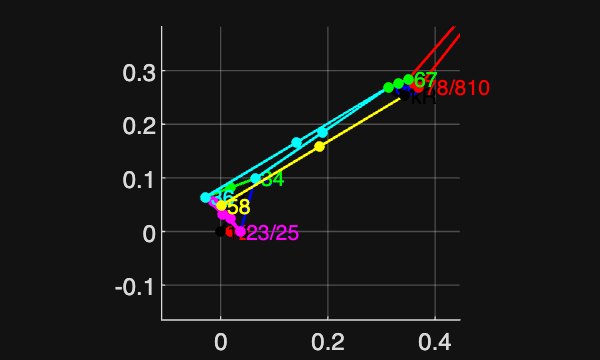

%% ───────── NUMERIC FUNCTION ─────────

vars = t_d;

f_anim = matlabFunction( ...
    P12, P14, P24, P34, P23_25_35, ...
    P36, P58, P69, P68, PkR, P78_810, P67, ...
    'Vars', vars);

%% ───────── ANIMATION ─────────

figure; clf; hold on;
axis equal;
grid on;

% Set viewing window (adjust if needed)
axis([-25 25 -25 25]);

% Angle sweep
t_vals = linspace(0, 4*pi, 200);

for t = t_vals
    
    % Evaluate all link points
    [P12n, P14n, P24n, P34n, P23n, ...
     P36n, P58n, P69n, P68n, PkRn, P78n, P67n] = f_anim(t);
    
    cla; % clear frame

xlim([-11.0 44.6]/100) % full view
ylim([-16.5 38.2]/100)
% xlim([-3.40 6.74]) % zoom in driving 4 bar
% ylim([-2.52 7.46])
% xlim([7.7 22.3])% zoom at 4 bar joint
% ylim([0.5 14.9])
    
    %% ── Plot each link ──
    
    plot_link(P12n, 'r', '12');   % crank
    plot_link(P14n, 'k', '14');   % ground
    plot_link(P24n, 'b', '24');
    plot_link(P34n, 'g', '34');
    plot_link(P23n, 'm', '23/25');
    plot_link(P36n, 'c', '36');
    plot_link(P58n, 'y', '58');
    plot_link(P69n, 'k', '69');
    plot_link(P68n, 'b', '68');
    plot_link(PkRn, 'k', 'kR');
    plot_link(P78n, 'r', '78/810');
    plot_link(P67n, 'g', '67');
    
    drawnow;
end

## Function 

function plot_link(P, color, name)
    plot(P(:,1), P(:,2), '-o', ...
        'Color', color, ...
        'LineWidth', 1, ...
        'MarkerSize', 3, ...
        'MarkerFaceColor', color);
    
    % Label first point (optional)
    text(P(1,1), P(1,2), [' ' name], ...
        'FontSize', 8, 'Color', color);
end



# Kinematics & Dynamics

## Inertia, Position, Velocity, KE & PE

syms t_d(t)
P12 = compose(P12, t_d(t));
P24 = compose(P24, t_d(t));
P34 = compose(P34, t_d(t));
P23_25_35 = compose(P23_25_35, t_d(t));
P36 = compose(P36, t_d(t));
P58 = compose(P58, t_d(t));
P69 = compose(P69, t_d(t));
P68 = compose(P68, t_d(t));
PkR = compose(PkR, t_d(t));
P78_810 = compose(P78_810, t_d(t));
P67 = compose(P67, t_d(t));
%easy way to delete video and use t_d(t) at the very beginning
t_23 = compose(t_23, t_d(t));
t_34 = compose(t_34, t_d(t));
t_78 = compose(t_78, t_d(t));

%% ───────── CM POSITION VECTORS ─────────
r12 = [P12(2,1); P12(2,2)];
r34 = [P34(2,1); P34(2,2)];

r23 = [P23_25_35(2,1); P23_25_35(2,2)];
r35 = [P23_25_35(4,1); P23_25_35(4,2)];
r25 = [P23_25_35(6,1); P23_25_35(6,2)];

r36 = [P36(2,1); P36(2,2)];
r46 = [P36(4,1); P36(4,2)];

r58 = [P58(2,1); P58(2,2)];
r69 = [P69(2,1); P69(2,2)];

r78  = [P78_810(2,1); P78_810(2,2)];
r710 = [P78_810(4,1); P78_810(4,2)];
r810 = [P78_810(6,1); P78_810(6,2)];

r67 = [P67(2,1); P67(2,2)];

%% ───────── MASSES (m = rho * length) ─────────
m_tot = 0.3;  %500g for 1 wing
rho_link = m_tot/(L710+L36); % density of material kg/m. 

m12  = rho_link * L12;
m34  = rho_link * L34;

m23  = rho_link * L23;
m25  = rho_link * L25;
m35  = rho_link * L35;

m36  = rho_link * L36;
m46  = rho_link * L46;

m58  = rho_link * L36 * (1+k);   
m69  = rho_link * L35; % same as 35

m78  = rho_link * L78;
m710 = rho_link * L710;
m810 = rho_link * L810;

m67  = rho_link * L67;

%% ───────── INERTIA (rod about CM) ─────────

I12  = (1/12)*m12*L12^2;
I34  = (1/12)*m34*L34^2;

I23  = (1/12)*m23*L23^2;
I25  = (1/12)*m25*L25^2;
I35  = (1/12)*m35*L35^2;

I36  = (1/12)*m36*L36^2;
I46  = (1/12)*m46*L46^2;

I58  = (1/12)*m58*(L36*(1+k))^2;
I69  = (1/12)*m69*L35^2;

I78  = (1/12)*m78*L78^2;
I710 = (1/12)*m710*L710^2;
I810 = (1/12)*m810*L810^2;

I67  = (1/12)*m67*L67^2;

%% ───────── VELOCITIES (CM) ─────────

v12  = diff(r12, t);
v34  = diff(r34, t);

v23  = diff(r23, t);
v25  = diff(r25, t);
v35  = diff(r35, t);

v36  = diff(r36, t);
v46  = diff(r46, t);

v58  = diff(r58, t);
v69  = diff(r69, t);

v78  = diff(r78, t);
v710 = diff(r710, t);
v810 = diff(r810, t);

v67  = diff(r67, t);

%% ───────── ANGULAR VELOCITIES ─────────

w12  = diff(t_d, t);

w23  = diff(t_23, t);
w25  = w23;
w35  = w23;   % same rigid body (coupler)

w34  = diff(t_34, t);
w36  = w34;
w46  = w34;   % same rigid body (follower)

w58  = w36;   % parallel to L36
w69  = w35;   % parallel to L35

w78  = diff(t_78, t);
w710 = w78;
w810 = w78;

t_67 = atan2(P67(3,2)-P67(1,2), P67(3,1)-P67(1,1));
w67  = diff(t_67, t);   % depends on rocker chain

%% ───────── KINETIC ENERGY ─────────

% T = ...
% 1/2*m12*(v12.'*v12)   + 1/2*I12*w12^2 + ...
% 1/2*m34*(v34.'*v34)   + 1/2*I34*w34^2 + ...
% 1/2*m23*(v23.'*v23)   + 1/2*I23*w23^2 + ...
% 1/2*m25*(v25.'*v25)   + 1/2*I25*w25^2 + ...
% 1/2*m35*(v35.'*v35)   + 1/2*I35*w35^2 + ...
% 1/2*m36*(v36.'*v36)   + 1/2*I36*w36^2 + ...
% 1/2*m46*(v46.'*v46)   + 1/2*I46*w46^2 + ...
% 1/2*m58*(v58.'*v58)   + 1/2*I58*w58^2 + ...
% 1/2*m69*(v69.'*v69)   + 1/2*I69*w69^2 + ...
% 1/2*m78*(v78.'*v78)   + 1/2*I78*w78^2 + ...
% 1/2*m710*(v710.'*v710) + 1/2*I710*w710^2 + ...
% 1/2*m810*(v810.'*v810) + 1/2*I810*w810^2 + ...
% 1/2*m67*(v67.'*v67)   + 1/2*I67*w67^2;

T = 1/2*m36*(v36.'*v36)   + 1/2*I36*w36^2 + ...
    1/2*m710*(v710.'*v710) + 1/2*I710*w710^2;

%% ───────── POTENTIAL ENERGY ─────────

% V = ...
% m12*g*r12(2) + ...
% m34*g*r34(2) + ...
% m23*g*r23(2) + ...
% m25*g*r25(2) + ...
% m35*g*r35(2) + ...
% m36*g*r36(2) + ...
% m46*g*r46(2) + ...
% m58*g*r58(2) + ...
% m69*g*r69(2) + ...
% m78*g*r78(2) + ...
% m710*g*r710(2) + ...
% m810*g*r810(2) + ...
% m67*g*r67(2);

V = m36*g*r36(2) + ...
    m710*g*r710(2);



## Lagrangian (Time Consuming. ~50min)

%% ───────── LAGRANGIAN ─────────
%L = (T - V);
t_d_dot = diff(t_d, t)

$$t\_d\_dot(t) = \frac{\partial }{\partial t}t_{d}\left(t\right)$$

dV = diff(V, t_d)

dTdq = diff(T,t_d)

dT = diff(diff(T,t_d_dot), t)

## Save Result (check point 1)

save('RB_Lagrange.mat')

clear all

load('RB_Lagrange.mat')

# Input

% define motion
freq = 3; % flapping frequency (Hz)
ang_freq = freq * 2 * pi; % rad/s
period = 1/freq; % period (s)

# Aerodynamics 

## Aerodynamic Effort Term

% link 36 & 710 normal velocity
L36_N = [L36y; -L36x]/L36;% normal vector for link 36, 90˚ CW to L36
L36_N = compose(L36_N, t_d(t));
L36_N = formula(L36_N);
v36_N_mag = dot(L36_N, v36);
v36_N = v36_N_mag * L36_N; % CM velocity vector's normal component

L710_N = [L710y; -L710x]/L710;% normal vector for link 710, 90˚ CW  (downward)
L710_N = compose(L710_N, t_d(t));
L710_N = formula(L710_N);
v710_N_mag = dot(L710_N,v710); % velocity positive if velocity is downward
v710_N = v710_N_mag * L710_N; % CM velocity vector's normal component



% divide linkage into segments
numSeg_36 = 5; % number of segment L36 is divided into
seg_36_x = linspace(-L36/2,L36/2,numSeg_36+1);  % segment dividing lines
seg_36_x = seg_36_x + 0.5*L36/numSeg_36;  % CM of each segment w.r.t. CM of L36
seg_36_x = seg_36_x(1:(end-1));

numSeg_710 = 5; % number of segment  
seg_710_x = linspace(-L710/2,L710/2,numSeg_710+1);  % segment dividing lines
seg_710_x = seg_710_x + 0.5*L710/numSeg_710;  % CM of each segment w.r.t. CM of L36
seg_710_x = seg_710_x(1:(end-1));



% define velocity
v36_profile = v36_N_mag - seg_36_x* w36; % magnitude of velocity normal to bar. v36 positive if it's downward
% w36 > 0, ccw, so positive distance means velocity component points up (negative)
v710_profile = v710_N_mag - seg_710_x * w710;  



% define area
A36 = L36*0.3;% chord  = 30cm
A36_seg = A36/numSeg_36; 
A710 = L710*0.3;% chord  = 30cm
A710_seg = A710/numSeg_710; 


% link 36 & 710 normal force (excluding coefficient)
F36_aero_sinC = 0.5*rho_air*A36_seg*(v36_profile.^2); % in direction of L36_N. A vector of 5 forces
F710_aero_sinC = 0.5*rho_air*A710_seg*(v710_profile.^2); % in direction of L710_N. A vector of 5 forces

e36_aero_sinC = (1/ang_freq)*dot(F36_aero_sinC,v36_profile); % work on wing always negative (F up, v down) (CW direction)
e710_aero_sinC = (1/ang_freq)*dot(F710_aero_sinC,v710_profile); % work on wing always negative (F up, v down)
    % converted to negative val in numerical step

## Aerodynamic Lift 

% projection of F_aero to y-axis
F36_N_mag = L36_N(2); % projection is same as the y component of normal vector
F710_N_mag = L710_N(2); % projection is same as the y component of normal vector

## Save Result (check point 2)

save('RB_Lagrange2.mat')

clear all

load('RB_Lagrange2.mat')

# Numerical Solution

## Numerical Substitution

% Specify motion w/o overwriting t_d  
t_d_fot     = ang_freq * t;          % td as function of time (fot)    
t_d_dot_fot = diff(t_d_fot, t);      % = ang_freq (constant)
t_d_ddot_fot= diff(t_d_dot_fot, t);  % = 0

% Substitute 
v710y_sub = subs(v710(2), [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]); 
            % CM710 velocity y component, function of t
e36_aero_sinC_sub  = subs(e36_aero_sinC,  [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]); 
e710_aero_sinC_sub = subs(e710_aero_sinC, [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]); 
% v36_sub         = subs(v36,   [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
% w36_sub         = subs(w36,   [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
% v710_sub        = subs(v710,  [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
% w710_sub        = subs(w710,  [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
% v36_N_mag_sub   = subs(v36_N_mag,  [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
% v710_N_mag_sub  = subs(v710_N_mag, [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);

% convert to numeric functions of t only
v710y_fun  = matlabFunction(v710y_sub,  'Vars', t);
e36_aero_sinC_fun   = matlabFunction(e36_aero_sinC_sub,   'Vars', t);
e710_aero_sinC_fun  = matlabFunction(e710_aero_sinC_sub,  'Vars', t);

% v36_fun    = matlabFunction(v36_sub,    'Vars', t);
% w36_fun    = matlabFunction(w36_sub,    'Vars', t);
% v710_fun   = matlabFunction(v710_sub,   'Vars', t);
% w710_fun   = matlabFunction(w710_sub,   'Vars', t);
% v36_N_mag_fun    = matlabFunction(v36_N_mag_sub,   'Vars', t);
% v710_N_mag_fun   = matlabFunction(v710_N_mag_sub,   'Vars', t);

% Evaluate over time
t_vals    = linspace(0, period, 200); % 1x200
v_vals    = v710y_fun(t_vals);
e36_aero_sinc_val = e36_aero_sinC_fun(t_vals);
e710_aero_sinc_val = e710_aero_sinC_fun(t_vals);
% v36_vals  = v36_fun(t_vals);
% w36_vals  = w36_fun(t_vals); 
% v710_vals = v710_fun(t_vals);
% w710_vals = w710_fun(t_vals); 

## Up vs Down Stroke Effort (e)

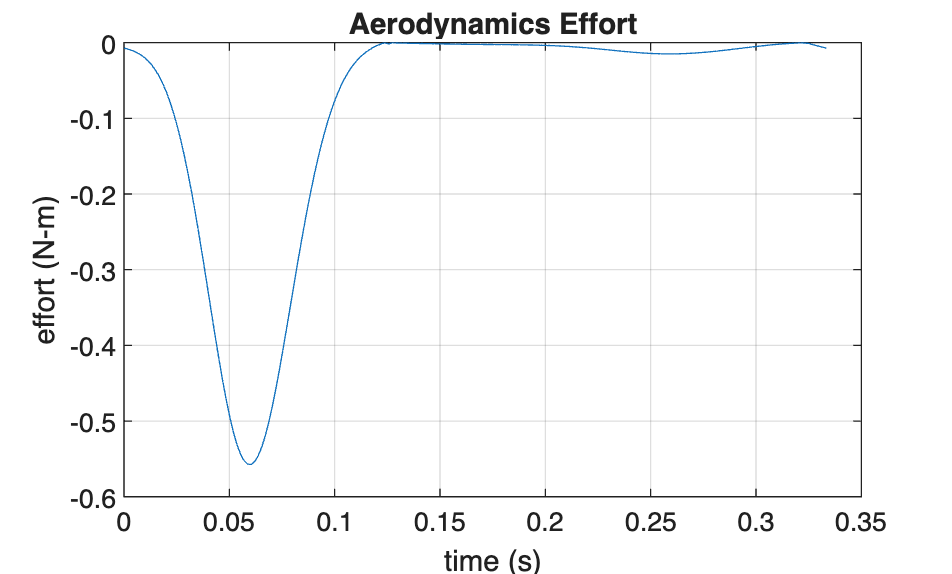

% define up & down stroke via CM710 velocity sign
isUpstroke = v_vals > 0;
e_terms = zeros(size(t_vals));

CL = 1;
CD = 0.1;
e_terms(isUpstroke)  = abs(e36_aero_sinc_val(isUpstroke)  + e710_aero_sinc_val(isUpstroke))  * -1* CD;
% upstroke: tau term is part of e but it's unknown
e_terms(~isUpstroke) = abs(e36_aero_sinc_val(~isUpstroke) + e710_aero_sinc_val(~isUpstroke)) *-1 * CL;
% down-stroke: tau term is part of e but it's unknown

figure
plot(t_vals, e_terms);
xlabel("time (s)")
ylabel("effort (N-m)")
title("Aerodynamics Effort")
grid on

## Lagrangian Terms (L)

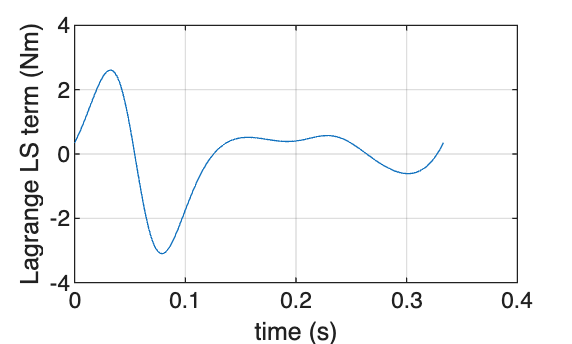

% numerical Lagrangian
dV_sub   = subs(dV,   [t_d, diff(t_d,t), diff(diff(t_d,t),t)], [t_d_fot, t_d_dot_fot, t_d_ddot_fot]); 
dTdq_sub = subs(dTdq, [t_d, diff(t_d,t), diff(diff(t_d,t),t)], [t_d_fot, t_d_dot_fot, t_d_ddot_fot]); 
dT_sub   = subs(dT  , [t_d, diff(t_d,t), diff(diff(t_d,t),t)], [t_d_fot, t_d_dot_fot, t_d_ddot_fot]);

dV_fun    = matlabFunction(dV_sub,    'Vars', t);
dTdq_fun  = matlabFunction(dTdq_sub,  'Vars', t);
dT_fun    = matlabFunction(dT_sub,    'Vars', t);

dV_vals   = dV_fun(t_vals); 
dTdq_vals = dTdq_fun(t_vals); 
dT_vals   = dT_fun(t_vals); 

L_ls_val = dT_vals - dTdq_vals + dV_vals; % left hand side of lagrange equation of motion

figure
plot(t_vals, L_ls_val);
xlabel("time (s)")
ylabel("Lagrange LS term (Nm)")
grid on

## Solve For Applied Torque 

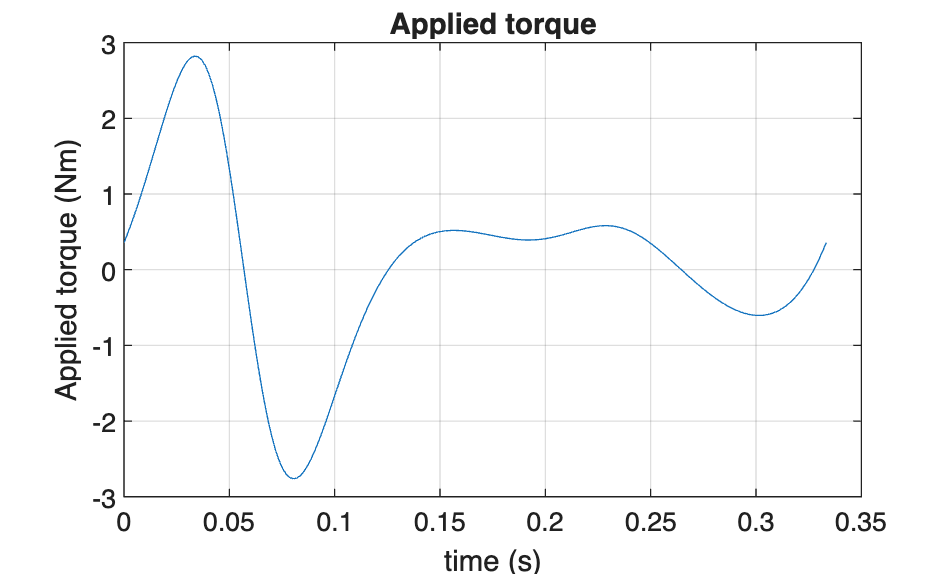

% need to change density!!!
tau_val = L_ls_val - e_terms;
figure
plot(t_vals, tau_val);
xlabel("time (s)")
ylabel("Applied torque (Nm)")
grid on
title("Applied torque")

## Lift Generation

%% ─────────F_aero SUBSTITUTION ─────────
F36_aero_sinC_sub = subs( ...
    F36_aero_sinC.', ...  % 5x1
    [t_d, diff(t_d,t), diff(diff(t_d,t),t)], ...
    [t_d_fot, t_d_dot_fot, t_d_ddot_fot]);

F710_aero_sinC_sub = subs( ...
    F710_aero_sinC.', ...
    [t_d, diff(t_d,t), diff(diff(t_d,t),t)], ...
    [t_d_fot, t_d_dot_fot, t_d_ddot_fot]);

F36_aero_sinC_fun = matlabFunction(F36_aero_sinC_sub, 'Vars', t);
F710_aero_sinC_fun = matlabFunction(F710_aero_sinC_sub, 'Vars', t);

F36_aero_sinC_vals = F36_aero_sinC_fun(t_vals); % vectors
F710_aero_sinC_vals = F710_aero_sinC_fun(t_vals);

%% ───────── NORMAL VECTOR Y-COMPONENT SUBSTITUTION ─────────
F36_N_mag_sub = subs(F36_N_mag, [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
F710_N_mag_sub = subs(F710_N_mag, [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);

F36_N_mag_fun = matlabFunction(F36_N_mag_sub, 'Vars', t);
F710_N_mag_fun = matlabFunction(F710_N_mag_sub, 'Vars', t);

F36_N_mag_vals = F36_N_mag_fun(t_vals); % scalars
F710_N_mag_vals = F710_N_mag_fun(t_vals);

%% ───────── VELOCITY PROFILE NUMERIC CONVERSION ─────────

% substitute motion (NO ddot needed) %5x1
v36_profile_sub  = subs(v36_profile.',  [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);
v710_profile_sub = subs(v710_profile.', [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);

% convert to numeric functions of time
v36_profile_fun  = matlabFunction(v36_profile_sub,  'Vars', t);
v710_profile_fun = matlabFunction(v710_profile_sub, 'Vars', t);

% evaluate over time
v36_profile_vals  = v36_profile_fun(t_vals);
v710_profile_vals = v710_profile_fun(t_vals);


%% ─────────% Calculate lift forces ───────── 
% (5x 200).* (1x200)
% -1 to compensate for sign of F36_N
F36_lift_sinC_vec  = -1*(F36_aero_sinC_vals .* F36_N_mag_vals).* sign(v36_profile_vals); 
F36_lift_sinC = sum(F36_lift_sinC_vec);

F710_lift_sinC_vec  = -1*(F710_aero_sinC_vals .* F710_N_mag_vals).* sign(v710_profile_vals); 
F710_lift_sinC = sum(F710_lift_sinC_vec);


F_36_lift_terms = zeros(size(t_vals));
F_710_lift_terms = zeros(size(t_vals));

F_36_lift_terms(isUpstroke)  = F36_lift_sinC(isUpstroke)  * CD;
F_36_lift_terms(~isUpstroke) = F36_lift_sinC(~isUpstroke) * CL;
F_710_lift_terms(isUpstroke)  = F710_lift_sinC(isUpstroke)  * CD;
F_710_lift_terms(~isUpstroke) = F710_lift_sinC(~isUpstroke) * CL;


% F36_lift_sinC_vec  = dot(F36_aero_sinC * F36_N_mag, sign(v36_profile)); % vector w/ 5 component
% F36_lift_sinC = sum(F36_lift_sinC_vec);
% 
% F710_lift_sinC_vec  = dot(F710_aero_sinC * F710_N_mag,  sign(v710_profile));
% F719_lift_sinC = sum(F710_lift_sinC_vec);
% 
% F36_lift_sinC_sub  = subs(F36_lift_sinC,   [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);  % sinC
% F710_lift_sinC_sub = subs(F710_lift_sinC,  [t_d, diff(t_d,t)], [t_d_fot, t_d_dot_fot]);  % sinC
% 
% F36_lift_sinC_fun   = matlabFunction(F36_lift_sinC_sub,    'Vars', t);
% F710_lift_sinC_fun  = matlabFunction(F710_lift_sinC_sub,   'Vars', t);
% 
% % Evaluate lift forces over time
% F36_lift_vals = F36_lift_sinC_fun(t_vals);
% F710_lift_vals = F710_lift_sinC_fun(t_vals);

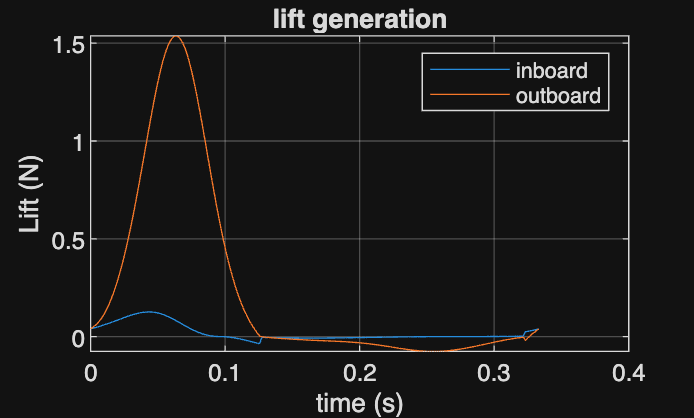


figure
plot(t_vals, F_36_lift_terms);
hold on
plot(t_vals, F_710_lift_terms);
xlabel("time (s)")
ylabel("Lift (N)")
legend('inboard', 'outboard')
grid on
title("lift generation")


% Average power consumption
% Calculate average power consumption
averagePower = mean(tau_val*ang_freq);
disp(['Average Power Consumption: ', num2str(averagePower), ' W']);

Average Power Consumption: 1.6448 W



averageLift = mean(F_36_lift_terms + F_710_lift_terms);
disp(['Average Lift Generation: ', num2str(averageLift), ' N']);

Average Lift Generation: 0.26469 N


## Save Result

save('RB_Lagrange3.mat')